stroke=readtable('C:\Users\Diego\OneDrive - Universidad Autonoma de Madrid\metodologia\TECNOLOGIA DEL CONOCIMIENTO\datos_TC\stroke.csv');
predictors=["age","avg_glucose_level","bmi"];
stroke(:,predictors)=normalize(stroke(:,predictors),"zscore");

-Construir matriz 100x2 de ceros para valores *p* 

-Construir matriz 100x2 de ceros para valores de precisión 

Repetir 100 veces:

    1. Filtrar casos stroke=No

    2. Extraer muestra aleatoria de casos No de tamaño 783 (número de casos stroke=Yes)

    3. Unir en única muestra 783 casos No y todos (783) los casos Yes

    4. Definir predictores y variable a predecir 

    5. Partición en conjunto de entrenamiento y conjunto de test

    6. Ajustar los diferentes modelos (LDA y QDA)  en  el mismo conjunto de entrenamiento y realizar predicciones sobre el mismo conjunto de test

    7. Construir prueba de McNemar a partir de la siguiente tabla de contingencia

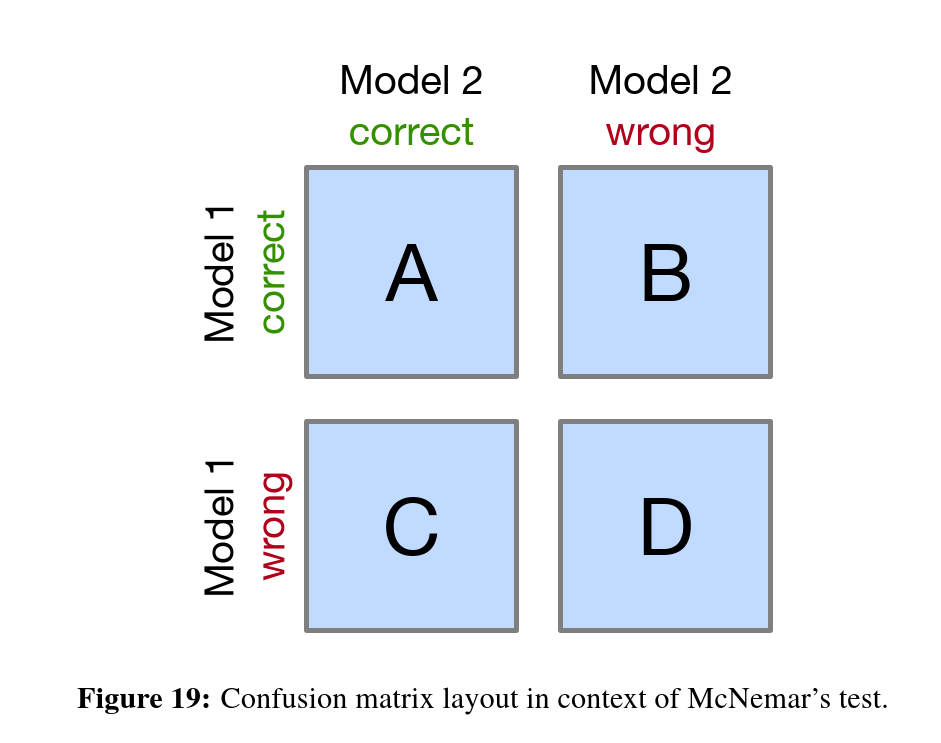

8. Añadir nivel crítico *p* a matriz de valores.

9. Calcular precisión de cada modelo de los dos comparados y añadir éstas a matriz de precisiones (la que compara modelo 1 vs 2 y la que compara modelo 1 vs 3). Estos valores permiten saber que modelo es superior en caso de nivel crítico estadísticamente significativo

pvalslda=zeros([100 2]); % p-values for the different model comparisons
pvalsqda=zeros([100 2]);
accs12=zeros([100 2]); % accuracies for model 1 and model 2
accs13=zeros([100 2]); % accuracies for model 1 and model 3
rng(13)

for i = 1:100
    
    no_stroke=stroke(stroke{:,'stroke'}==0,:); % filter class 'No'
    ids=randsample(no_stroke{:,'Var1'},783); % extract 783 random ids
    
    samp=[stroke(ids,:) ; stroke(stroke{:,'stroke'}==1,:)]; % join the 783+783 cases
    
    zage=samp{:,'age'};
    zbmi=samp{:,'bmi'};
    zglucose=samp{:,'avg_glucose_level'};
    group=samp{:,'stroke'}; % target
    
    % split dataset in train set and test set
    c=cvpartition(length(group),'HoldOut',.3);
    ids_train=training(c);
    ids_test=test(c);
        
    % age as predictor LDA
    lda1=fitcdiscr(zage(ids_train),group(ids_train), ...
        "DiscrimType","linear");
    
    % age+glucose as predictors LDA
    lda2=fitcdiscr([zage(ids_train) zglucose(ids_train)],group(ids_train), ...
        "DiscrimType","linear");
    
    % age+bmi as predictors LDA
    lda3=fitcdiscr([zage(ids_train) zbmi(ids_train)],group(ids_train), ...
        "DiscrimType","linear");
    
    % predictions LDA...............
    preds1_test=lda1.predict(zage(ids_test));
    preds2_test=lda2.predict([zage(ids_test) zglucose(ids_test)]);
    preds3_test=lda3.predict([zage(ids_test) zbmi(ids_test)]);
    
    % comparisons....................
    % lda1 correct and lda2 incorrect
    b=nnz(preds1_test==group(ids_test) & preds2_test~=group(ids_test));
    % lda1 incorrect and lda2 correct
    c=nnz(preds1_test~=group(ids_test) & preds2_test==group(ids_test));
   
    mcnemar= (abs(b-c)-1)^2 / (b+c);
    pval=chi2cdf(mcnemar,1,'upper'); 
    pvalslda(i,1)=pval; % update matrix of LDA p-values
    accs12(i,:)=[mean(preds1_test==group(ids_test)) mean(preds2_test==group(ids_test))];
    
    % lda1 correct and lda3 incorrect
    b=nnz(preds1_test==group(ids_test) & preds3_test~=group(ids_test));
    % lda1 incorrect and lda3 correct
    c=nnz(preds1_test~=group(ids_test) & preds3_test==group(ids_test));
    
    mcnemar= (abs(b-c)-1)^2 / (b+c);
    pval=chi2cdf(mcnemar,1,'upper'); 
    pvalslda(i,2)=pval; % update matrix of LDA p-values
    accs13(i,:)=[mean(preds1_test==group(ids_test)) mean(preds3_test==group(ids_test))];
    %--------------------------------  same but with QDA
    
    % age as predictor QDA
    qda1=fitcdiscr(zage(ids_train),group(ids_train), ...
        "DiscrimType","quadratic");
    
    % age+glucose as predictors QDA
    qda2=fitcdiscr([zage(ids_train) zglucose(ids_train)],group(ids_train), ...
        "DiscrimType","quadratic");
    
    % age+bmi as predictors QDA
    qda3=fitcdiscr([zage(ids_train) zbmi(ids_train)],group(ids_train), ...
        "DiscrimType","quadratic");
    
    % predictions...............
    preds1_test=qda1.predict(zage(ids_test));
    preds2_test=qda2.predict([zage(ids_test) zglucose(ids_test)]);
    preds3_test=qda3.predict([zage(ids_test) zbmi(ids_test)]);
    
    % lda1 correct and lda2 incorrect
    b=nnz(preds1_test==group(ids_test) & preds2_test~=group(ids_test));
    % lda1 incorrect and lda2 correct
    c=nnz(preds1_test~=group(ids_test) & preds2_test==group(ids_test));
    
    mcnemar= (abs(b-c)-1)^2 / (b+c);
    pval=chi2cdf(mcnemar,1,'upper'); 
    pvalsqda(i,1)=pval; % update matrix of QDA p-values
    
    % qda1 correct and qda3 incorrect
    b=nnz(preds1_test==group(ids_test) & preds3_test~=group(ids_test));
    % qda1 incorrect and qda3 correct
    c=nnz(preds1_test~=group(ids_test) & preds3_test==group(ids_test));
    
    mcnemar= (abs(b-c)-1)^2 / (b+c);
    pval=chi2cdf(mcnemar,1,'upper'); 
    pvalsqda(i,2)=pval; % update matrix of QDA p-values
        
end
mean(pvalslda<0.05)

ans =     0.0900    0.5000


mean(pvalsqda<0.05)

ans =     0.0600    0.4600


mean(accs12)

ans =     0.7637    0.7694


mean(accs13)

ans =     0.7637    0.7359


Una vez compobado que variables resultan más adecuadas se comparan modelos LDA y QDA con mismas variables para saber si es preferible emplear LDA o QDA. Para la comparación se realiza el mismo proceso que anteriormente.

pvals=zeros([100 1]);
accs=zeros([100 2]);

rng(13)
for i = 1:100
    
    no_stroke=stroke(stroke{:,'stroke'}==0,:); % filter class 'No'
    ids=randsample(no_stroke{:,'Var1'},783); % extract 783 random ids
    
    samp=[stroke(ids,:) ; stroke(stroke{:,'stroke'}==1,:)]; % join the 783+783 cases
    
    zage=samp{:,'age'};
    zbmi=samp{:,'bmi'};
    zglucose=samp{:,'avg_glucose_level'};
    group=samp{:,'stroke'}; % target
    
    c=cvpartition(length(group),'HoldOut',.3);
    ids_train=training(c);
    ids_test=test(c);
    
    % age+bmi as predictors LDA
    lda3=fitcdiscr([zage(ids_train)],group(ids_train), ...
        "DiscrimType","linear");
    
    % age+bmi as predictors QDA
    qda3=fitcdiscr([zage(ids_train)],group(ids_train), ...
        "DiscrimType","quadratic");
    
    % lda vs qda predictions
    predslda_test=lda3.predict([zage(ids_test)]);
    predsqda_test=qda3.predict([zage(ids_test)]);
    
    % lda1 correct and qda1 incorrect
    b=nnz(predslda_test==group(ids_test) & predsqda_test~=group(ids_test));
    % lda1 incorrect and qda1 correct
    c=nnz(predslda_test~=group(ids_test) & predsqda_test==group(ids_test));
    
    mcnemar= (abs(b-c)-1)^2 / (b+c);
    pval=chi2cdf(mcnemar,1,'upper'); 
    pvals(i,1)=pval;
    accs(i,:)=[mean(predslda_test==group(ids_test)) mean(predsqda_test==group(ids_test))];

end
mean(pvals<0.05)

ans = 0.0200

mean(accs)

ans =     0.7637    0.7614


Comparación visual de fronteras de decisión de ambos modelos. Para ello no se repite el proceso de ajuste y realización de predicciones 100 veces como en las ocasiones anteriores. Simplemente se ajusta una vez y ambos en los mismos datos

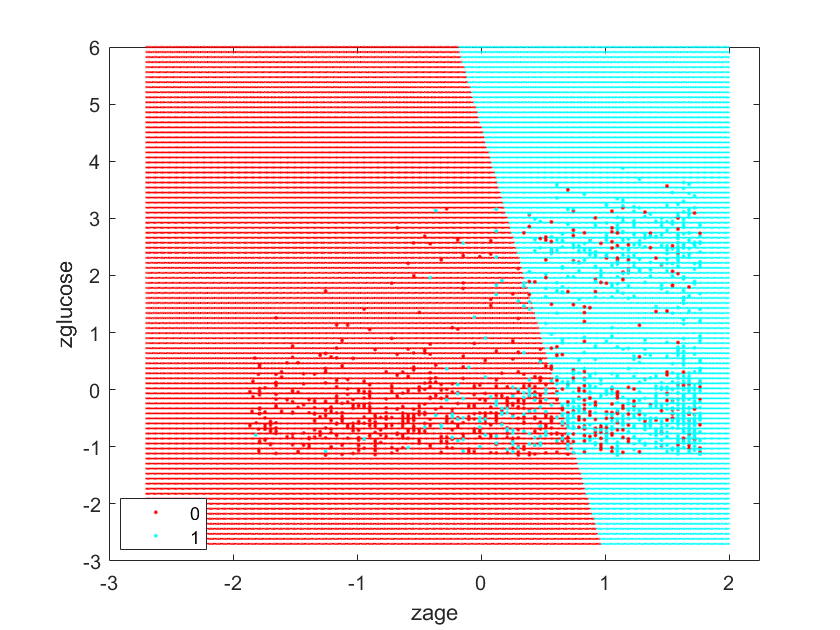

% plots................
rng(13);
no_stroke=stroke(stroke{:,'stroke'}==0,:); % filter class 'No'
ids=randsample(no_stroke{:,'Var1'},783); % extract 783 random ids

samp=[stroke(ids,:) ; stroke(stroke{:,'stroke'}==1,:)]; % join the 783+783 cases

zage=samp{:,'age'};
zbmi=samp{:,'bmi'};
zglucose=samp{:,'avg_glucose_level'};
group=samp{:,'stroke'}; % target

c=cvpartition(length(group),'HoldOut',.3);
ids_train=training(c);
ids_test=test(c);

% age+bmi as predictors LDA
lda3=fitcdiscr([zage(ids_train) zglucose(ids_train)],group(ids_train), ...
    "DiscrimType","linear");

% age+bmi as predictors QDA
qda3=fitcdiscr([zage(ids_train) zglucose(ids_train)],group(ids_train), ...
    "DiscrimType","quadratic");
    
[A B]=meshgrid(linspace(-2.7,2,500),linspace(-2.7,6,100));
A=A(:);
B=B(:);

pred=lda3.predict([A B]); 
h=gscatter(A,B,pred);
set(h,'Linewidth',2,'Markersize',2)
hold on
gscatter(zage,zglucose,group)
hold off

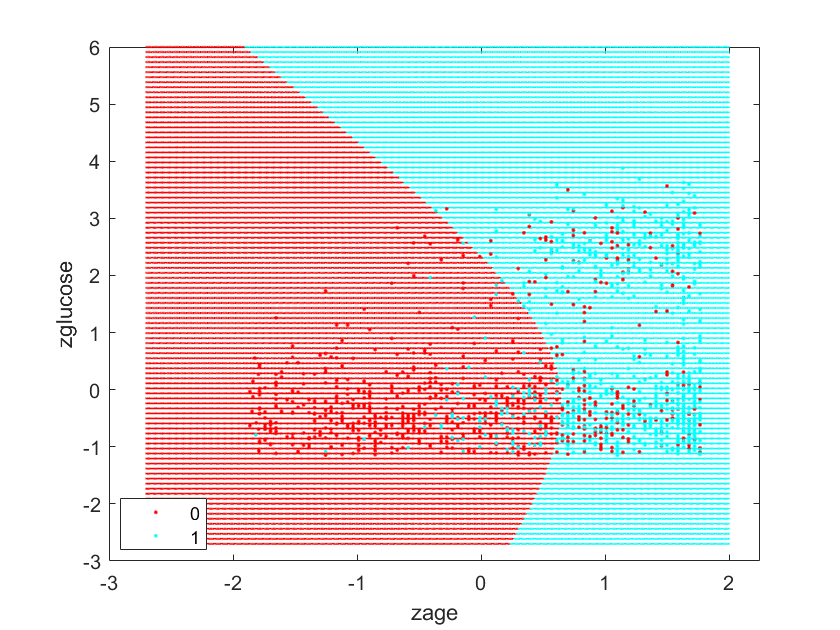


pred=qda3.predict([A B]); 
h=gscatter(A,B,pred);
set(h,'Linewidth',2,'Markersize',2)
hold on
gscatter(zage,zglucose,group)
hold off

Evaluación final de modelo QDA con *age* y *glucose* como predictores mediante validación cruzada. La matriz de confusión es el resultado de sumar las matrices de confusón de los 10 modelos de la validación cruzada. Como se sigue manteniendo el problema de clases desequilibradas, se repite el proceso de submuestreo

-Contruir matriz de confusión inicial 2x2 de ceros

Repettir 100 veces:

    1. Filtrar casos stroke=No

    2. Extraer muestra aleatoria de casos No de tamaño 783 (número de casos stroke=Yes)

    3. Unir en única muestra 783 casos No y todos (783) los casos Yes

    4. Definir predictores y variable a predecir.

    5. Ajustar modelo sin y con matriz de costes mediante validación cruzada

    6. Almacenar predicciones y emplearlas para construir matriz de confusión

    7. Actualizar matriz de confusión sumando valores 

% initial empty confusion matrices
conf_qda=[0 0;0 0];
conf_qdacost=[0 0;0 0];
iters=100;
rng(13);
for i = 1:iters
    
    no_stroke=stroke(stroke{:,'stroke'}==0,:); % filter class 'No'
    ids=randsample(no_stroke{:,'Var1'},783); % extract 783 random ids
    
    samp=[stroke(ids,:) ; stroke(stroke{:,'stroke'}==1,:)]; % join the 783+783 cases
    
    zage=samp{:,'age'};
    zbmi=samp{:,'bmi'};
    group=samp{:,'stroke'}; % target
    
    % age+glucose as predictors
    qda=fitcdiscr([zage zglucose],group, ...
        "DiscrimType","quadratic",'CrossVal','on');
    qda_cost=fitcdiscr([zage zglucose],group, ...
        "DiscrimType","quadratic",'CrossVal','on','Cost',[0 1;2 0]);
    
    predictions=kfoldPredict(qda);
    predictions_cost=kfoldPredict(qda_cost);
    
    % update confusion matrices
    conf_qda = conf_qda+confusionmat(group,predictions); 
    conf_qdacost = conf_qdacost+confusionmat(group,predictions_cost);
    
end

conf_qda

conf_qda =        53788       24512
       11032       67268


accuracy_lda=sum(diag(conf_qda))/(length(group)*iters)

accuracy_lda = 0.7730

sensitivity_lda=conf_qda(2,2)/(conf_qda(2,2)+conf_qda(2,1))

sensitivity_lda = 0.8591

specificity_lda=conf_qda(1,1)/(conf_qda(1,1)+conf_qda(1,2))

specificity_lda = 0.6869


conf_qdacost

conf_qdacost =        46755       31545
        6608       71692


accuracy_qdacost=sum(diag(conf_qdacost))/(length(group)*iters)

accuracy_qdacost = 0.7564

sensitivity_qdacost=conf_qdacost(2,2)/(conf_qdacost(2,2)+conf_qdacost(2,1))

sensitivity_qdacost = 0.9156

specificity_qdacost=conf_qdacost(1,1)/(conf_qdacost(1,1)+conf_qdacost(1,2))

specificity_qdacost = 0.5971